# `Project 1: SIR vs SEIRD (Sparsh Gupta & Ari Bobesh)`

# `How do SIR and SEIRD models differ for disease transmission?`

#### `Computational Essay`

`sgupta1@olin.edu                 abobesh@olin.edu`

## `Question `

**What are the key differences between the SIR and SEIRD models for disease transmission, particularly in how they differ in predicting the time and intensity of a secondary wave, when fit to the same first wave, across a range of infectivity values?**

This question is an explanatory question because it assesses how the differences within the models’ structure lead to differing results.

This is an important question to ask when choosing the proper model for a specific disease. It also helps to understand how different models behave given similar starting behavior as a result of their assumptions and construction. It is crucial that epidemiologists apply the proper model to the proper scenario because that can result in a correct and efficient allocation of resources. If a model falsly predicts an increase in infections, preparations made by hospitals and medical centers would be for nothing. On the other hand, failing to predict a surge in infections would lead to an underprepared medical system and an increase in deaths.

To understand the modeling choices made in this study, it is necessary to discuss how the modeling parameters were chosen. The COVID-19 virus was used as a baseline for both models in terms of death rate, recovery speed, and incubation time. The re-susceptibility rate was chosen arbitrarily in order to fit the modeling window and make comparisons between models easier.

To gather background information about the question, a literature search is conducted in the form of a Research Synthesis Matrix:

Research Synthesis Matrix 

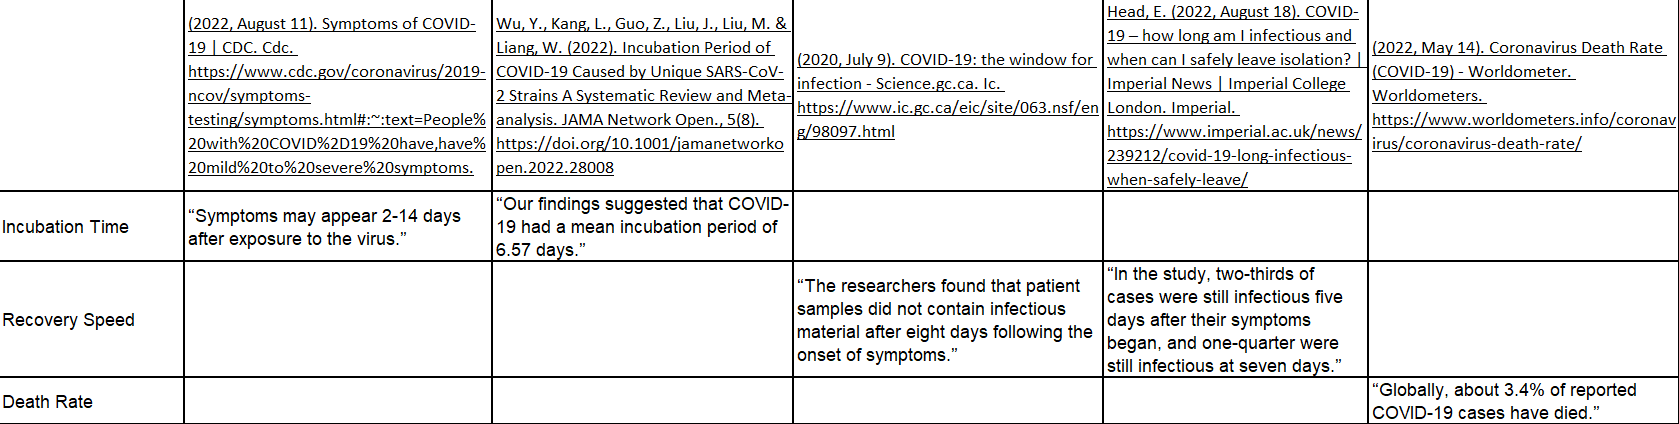

## `Methodology/Model`

In this study, we are going to look at the SIR and SEIRD models. SIR stands for Susceptible, Infected, Recovered and can be modeled with three stocks. The SEIRD model adds the Exposed and Dead stocks. Compared to the SIR model, the SEIRD model is viewed as a more realistic way of modeling diseases because it takes into account the incubation period between when a person is Exposed and Infectious.

The stock-and-flow digram for the SEIRD model 

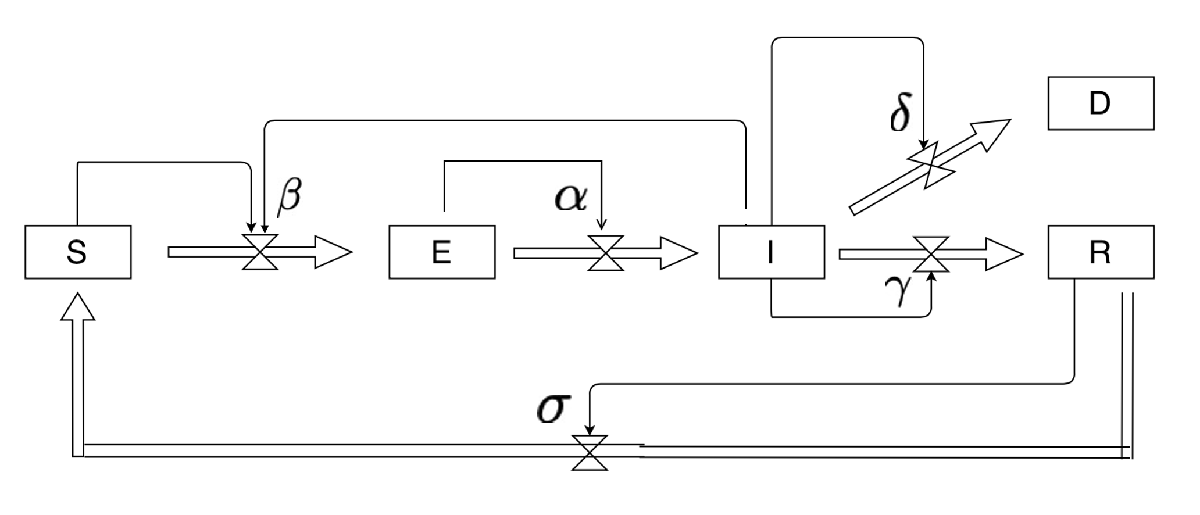

The update equations being used in the SEIRD model


$$S_{n+1} = S_{n} - \beta I S + \sigma R
\\
E_{n+1} = E_{n} - \alpha E  + \beta I S
\\
I_{n+1} = I_{n} - \gamma I  - \delta I  + \alpha E
\\
R_{n+1} = R_{n} - \sigma R  + \gamma I
\\
D_{n+1} = D_{n} + \delta I
$$


The SEIRD model has multiple assumptions, but the greatest being that natural births and deaths cancel out leaving only the deaths by the disease itself. This is an acceptable assumption because natural births and deaths are relatively balanced within the short-term across which the model is simulated. The models also assume that keeping the re-susceptibility parameter the same across both, albeit chosen arbitrarily, does not influence the visible differences in behavior holistically. This assumption is acceptable because the modeling question looks at overall trends in model results and infectivity sensitivity rather than disease-specific characteristics.

Stocks in the SEIRD model:

- S represents the number of Susceptible people in the model

- E represents the number of Exposed people in the model

- I represents the number of Infectious people in the model

- R represents the number of Recovered people in the model

- D represents the number of Dead people in the model

Flows in the SEIRD model:

- The flow from S to E represents susceptible people getting exposed

- The flow from E to I represents exposed people becoming infectious

- The flow from I to D represents infectious people dying

- The flow from I to R represents infectious people recovering

- The flow from R to S represents recovered people becoming re-susceptible

The parameters in the SEIRD model were set by taking into account the following:

$\alpha$** (incubation time): **

The incubation time of COVID is on average 8 days according to the CDC. A person starts at 100% health and is considered infectious at 25% health. With each passing week, a person's current health is multiplied by alpha to calculate their new health. This calibration was used to find a value of 30/100 for alpha where after 8 days a person is considered infectious.

$\beta$** (infectivity): **

The parameter beta is within the range of 0.005 and 0.2. These values were chosen as bounds because below 0.005 the simulation time frame is insufficient to produce results and above 0.2 the metrics measured become almost entirely linear and parallel for both models. The infectivity for the SIR model was standardized to the infectivity of the SEIRD model by aligning their peaks of Wave 1. At the same infectivity, the models behave very differently from the start, which would invalidate Wave 2 results.

$\gamma$** (recovery): **

The recovery time for COVID was found to be approximately one week. A person starts at 100% infectiousness and is considered recovered at 25% infectiousness. With each passing week, a person's current infectiousness is multiplied by gamma to calculate their new infectiousness. This calibration was used to find a value of 1/4 where after 7 days a person is considered healthy and non-infectious.

$\delta$** (death): **

The death rate of COVID is 1/30.

$\sigma$** (re-susceptibility):**

 This parameter is arbitrary such that the models produce results within the simulation window.

Verification:

There are four verification facts used to ensure that the SEIRD model functions as expected:

- Conservation of People Violated: The total number of people has either exceeded or fallen below the starting value.

- Antipeople Discovered: A stock is experiencing negative people.

- Birth Control Mishap: A stock has more than the initial number of people in the simulation.

- Walking Dead: The Dead stock is decreasing.

% assert(all(abs(S_seird + E_seird + I_seird + R_seird + D_seird - 100) < 1e-3), ...
%    "Conservation of People Violated")
%
% assert(all(S_seird>=0)||all(E_seird>=0)||all(I_seird>=0)||all(R_seird>=0)||all(D_seird>=0), ...
%    "Antipeople Discovered")
%
% assert(all(S_seird<=100)||all(E_seird<=100)||all(I_seird<=100)||all(R_seird<=100)|| ...
%    all(D_seird<=100), "Birth Control Mishap")
%
% assert(all((D_seird(2:end)-D_seird(1:(end-1)))>=0), "Walking Dead")

## `Result`

The two metrics used to model the key differences between SIR and SEIRD are:

- The peak number of infected people on the second wave of the virus.

- The week (time) when the second wave occurs. 

These metrics were swept by changing the value of the infectivity parameter (beta). They are appropriate because the models were fit to the first wave to eliminate confounding variables. These metrics also help answer the guiding question of how the differences between the SIR and SEIRD models reflect on their predictions of Wave 2.

#### Sensitivity Analysis using Parameter Sweeps for SIR and SEIRD

To accurately compare the SIR and SEIRD models as to their Wave 2 results, it is necessary to fit them both to Wave 1. To do this, we first run the SIR model across a range of infectivities and catalog what the results are. Then, we search the catalog to match the SEIRD model's infectivity to that of the SIR model that most closely matches the Wave 1 peak.

The code below sets the simulation variables and sets up parameter sweeps across infectivity for both the SIR and SEIRD models. 

% Time
week_end = 1000;

%Parameters
alpha_middle = 30/100;
beta_middle  = 1/27; 
gamma_middle = 1/4;
delta_middle = 1/30;
sigma_middle = 1/66;

beta_end = 0.2;
beta_start = 0.005;
Beta_all_SIR = linspace(0.00001, 0.02, 10000);
Beta_all_SEIRD = linspace(beta_start, beta_end, 500);

% Initial number of people
i_0 = 2;         
s_0 = 100 - i_0;
r_0 = 0;
e_0 = 6;
d_0 = 0;

The vectors below perform specific functions in fitting the models to the same first wave. The maxima vectors store the maximum number of infected people and the maxidx vectors store the week at which that maximum occurs. The number in the variable name identifies for which wave the vector is storing data. The vectors are finally identified as either pertaining to the SIR or SEIRD models. The vectors without wave identifiers are used for tracking our metrics. Finally, the infectivitySIR vector stores the infectivity of the SIR model as a function of the infectivity of the SEIRD model and peakShift is used to shift the SIR model horizontally to align the Wave 1 peaks of both models.

%SIR parameter sweep
maximaSIR = zeros(size(Beta_all_SEIRD));
maxidxSIR = zeros(size(Beta_all_SEIRD));
maxima1SIR = zeros(size(Beta_all_SIR));
maxidx1SIR = zeros(size(Beta_all_SIR));
maxima2SIR = zeros(size(Beta_all_SIR));
maxidx2SIR = zeros(size(Beta_all_SIR));
infectivitySIR = zeros(size(Beta_all_SEIRD));
peakShift = zeros(size(Beta_all_SEIRD));

%SEIRD parameter sweep
maximaSEIRD = zeros(size(Beta_all_SEIRD));
maxidxSEIRD = zeros(size(Beta_all_SEIRD));
maxima1SEIRD = zeros(size(Beta_all_SEIRD));
maxidx1SEIRD = zeros(size(Beta_all_SEIRD));

The code below iterates over the infectivity sweep of the SIR model and saves the data for the first and second waves.

for j = 1:length(Beta_all_SIR)

    beta_i = Beta_all_SIR(j);
    [S_b, I_b, R_b, W_b] = simulate_sir_v3( ...
        s_0, i_0, r_0, beta_i, gamma_middle, sigma_middle, week_end);

    [tempmax,tempidx] = findpeaks(I_b);
    try
        maxima1SIR(j)=tempmax(1);
        maxidx1SIR(j)=tempidx(1);
    catch error
    end
    try
        maxima2SIR(j)=tempmax(2);
        maxidx2SIR(j)=tempidx(2);
    catch error
    end
end

The code below runs the infectivity sweep over the SEIRD model, compares the results of Wave 1 to the SIR model, finds the appropriate SIR infectivity such that the models are fit to Wave 1, and then finally saves the metrics from the SIR and SEIRD second waves.

for j = 1:length(Beta_all_SEIRD)

    beta_i = Beta_all_SEIRD(j);
    [S_b, E_b, I_b, R_b, D_b, W_b] = simulate_seird( ...
        s_0-e_0, e_0, i_0, r_0, d_0, alpha_middle, beta_i, ...
        gamma_middle, delta_middle, sigma_middle, week_end);

    [tempmax,tempidx] = findpeaks(I_b);
    maxima1SEIRD(j)=tempmax(1);
    maxidx1SEIRD(j)=tempidx(1);
    difference=maxima1SIR-maxima1SEIRD(j);
    idx=zeros(1,100);
    for i=1:100
        temp=find((abs(difference)<=(0.01-i/10000)),1);
        try
            idx(i)=temp;
        catch error
        end
    end
    try
        nonzero=find(idx);
        infectivitySIR(j)=Beta_all_SIR(idx(nonzero(end)));
        peakShift(j)=maxidx1SEIRD(j)-maxidx1SIR(idx(nonzero(end)));
        maximaSIR(j)=maxima2SIR(idx(nonzero(end)));
        maxidxSIR(j)=maxidx2SIR(idx(nonzero(end)));
    catch error
    end
    try
        maximaSEIRD(j)=tempmax(2);
        maxidxSEIRD(j)=tempidx(2);
    catch error
    end
end

The combinedInfectivity variable makes a catalogue of the SIR infectivities that correlate to the respective SEIRD infectivities.

combinedInfectivity = [Beta_all_SEIRD;infectivitySIR];

This code plots the standardized infectivities, shift in Wave 1 peaks, maximum number of people infected on Wave 2, and the week when the maximum number of people are infected in Wave 2.

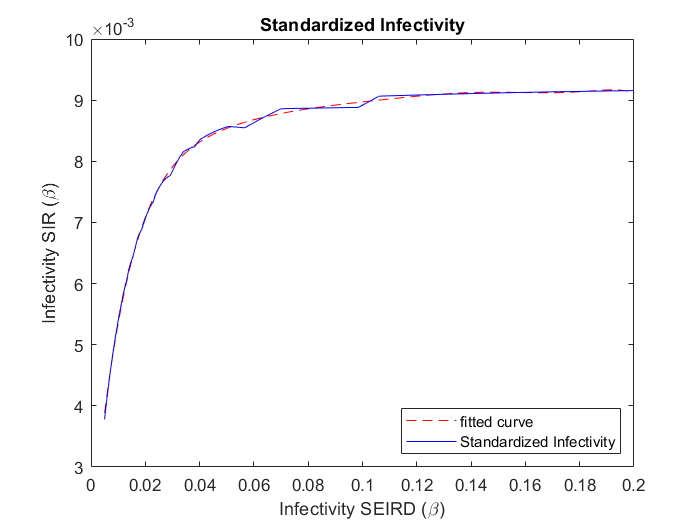

%Plotting
figure()

[curvefit,gof] = fit(Beta_all_SEIRD',infectivitySIR','poly8', ...
    'Normalize','on');
plot(curvefit,"r--")
hold on;
plot(Beta_all_SEIRD, infectivitySIR, "b-", "DisplayName", ...
    "Standardized Infectivity")
hold off;
xlabel('Infectivity SEIRD (\beta)')
ylabel('Infectivity SIR (\beta)')
title("Standardized Infectivity")
legend("Location","southeast")

This plot shows what SEIRD infectivity value and which SIR infectivity value result in similar Wave 1 characteristics.

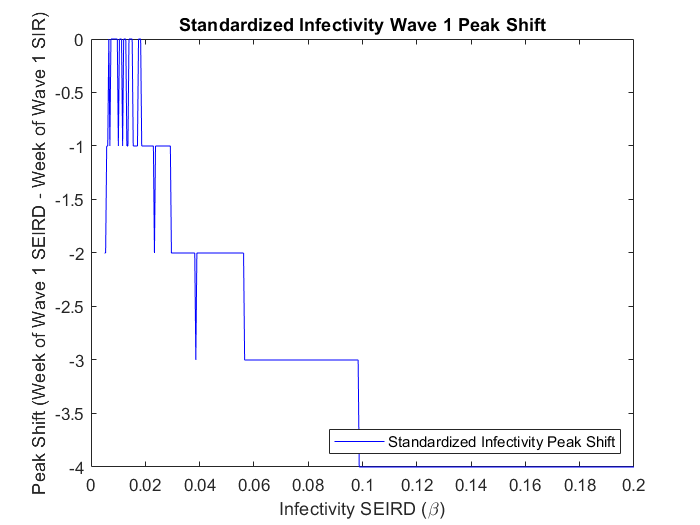

plot(Beta_all_SEIRD, peakShift, "b-", "DisplayName", ...
    "Standardized Infectivity Peak Shift")
xlabel('Infectivity SEIRD (\beta)')
ylabel('Peak Shift (Week of Wave 1 SEIRD - Week of Wave 1 SIR)')
title("Standardized Infectivity Wave 1 Peak Shift")
legend("Location","southeast")

The Peak Shift of Wave 1 ranges between -4 and 0 where negative values mean that the first wave of the SIR model occurs after that of the SEIRD model. This is later used to shift the SIR model horizontally to compensate for the difference.

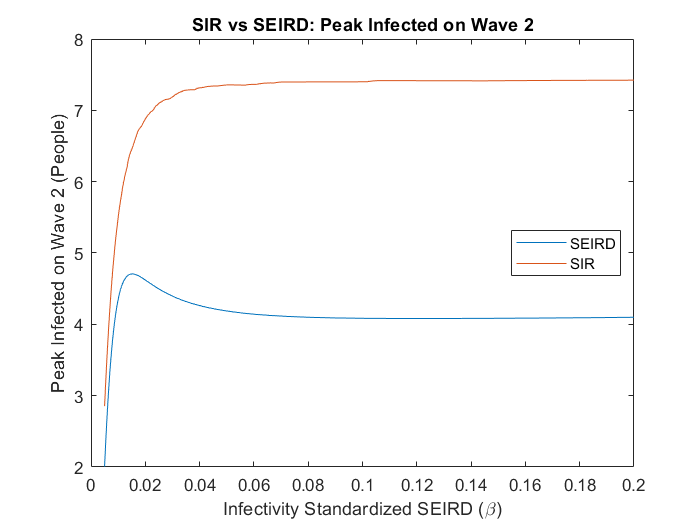

plot(Beta_all_SEIRD, maximaSEIRD, "DisplayName", "SEIRD")
hold on;
plot(Beta_all_SEIRD, maximaSIR, "DisplayName", "SIR")
hold off;
xlabel('Infectivity Standardized SEIRD (\beta)')
ylabel('Peak Infected on Wave 2 (People)')
title("SIR vs SEIRD: Peak Infected on Wave 2")
legend("Location","east")

Both models predict an eventual plateau in the peak number infected in the second wave as infectivity increases; however, the SIR model predicts a much higher value of around 7.5 compared to the 4 of the SEIRD model.

The graph also presents a difference in behavior with the SIR model increasing in the form of a logistic curve whereas the SEIRD model increases in a parabolic style then decreases similar to 1/x.

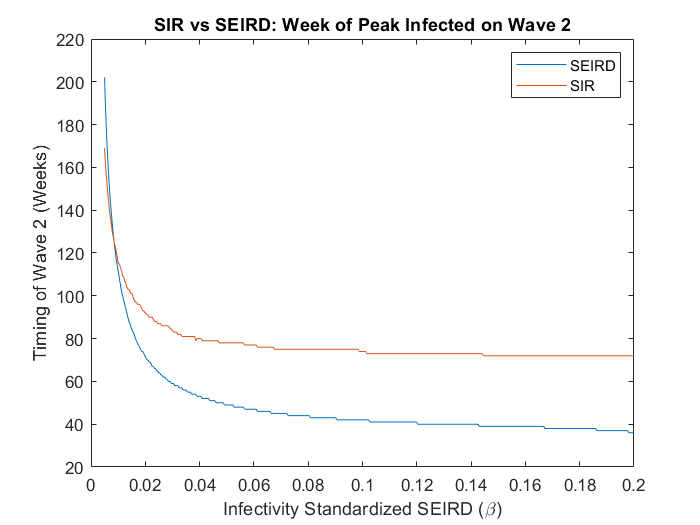

plot(Beta_all_SEIRD, maxidxSEIRD, "DisplayName", "SEIRD")
hold on;
plot(Beta_all_SEIRD, maxidxSIR+peakShift, "DisplayName", "SIR")
hold off;
xlabel('Infectivity Standardized SEIRD (\beta)')
ylabel('Timing of Wave 2 (Weeks)')
title("SIR vs SEIRD: Week of Peak Infected on Wave 2")
legend()

For the timing of the second wave, the models follow a similar shaped curve similar to 1/x, but the two curves diverge farther as infectivity increases, with the SIR model predicting a much later peak than the SEIRD model. Both models stabilize with the SIR model doing so around 75 weeks and the SEIRD model around 35 weeks,

The most important trends that are noticeable in the parameter sweeps are:

- The models diverge in both sweeps as infectivity increases, but both reach plateaus around the same time (approximately an standardized beta value of 0.05 or greater).

- SIR will almost always predict a later and more powerful second wave when compared to SEIRD, becoming more distinct as the infectivity and size of the first wave increase (divergence accelerates starting around a standardized beta value of 0.01).

- The decrease in the size of the second wave by the SEIRD model, occurring around a standardized beta value of 0.02, although slight, is interesting to note. 

- An important trend to note which both models agree upon is how an increase in infectivity will make the second wave arrive sooner.

The results of the parameter sweeps demonstrate how the models differ in predicting the second wave even when normalized by their first wave. They also show that the models are most sensitive to changes in standardized beta along the range 0.01 to 0.05.

The models are now simulated for a total population of 100 people with a standardized beta value of 0.0234. The graphs below provide a visual basis for how the models differ in infectivity over time and how the SEIRD model functions.

#### **Model Simulation with 100 people**

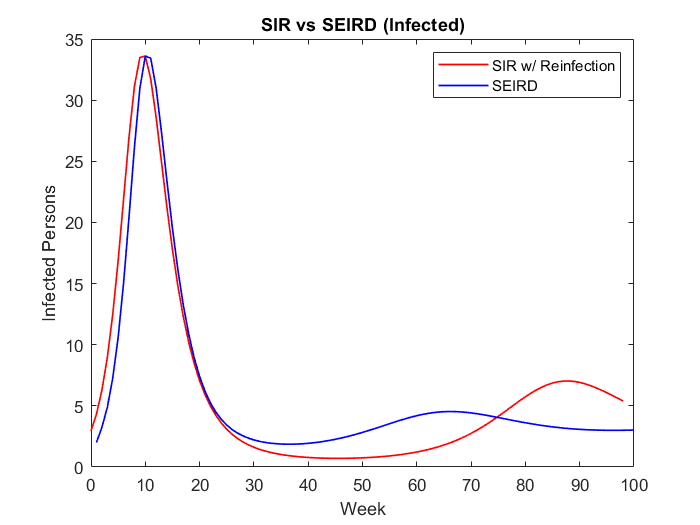

index=48; %Standard index is 48, range 1-500

% SIR parameters
beta_sir  = combinedInfectivity(2,index);     % Infection rate
gamma_sir = 1/4;                              % Recovery rate
delta_sir = 1/66;                             % Re-susceptible rate

% SEIRD parameters
alpha_seird = 30/100;                         % Infection rate
beta_seird  = combinedInfectivity(1,index);   % Exposure rate
gamma_seird = 1/4;                            % Recovery rate
delta_seird = 1/30;                           % Death rate
sigma_seird = 1/66;                           % Re-susceptible rate

% Time period
week_end = 100;

% Initial number of people
i_0 = 2;         
s_0 = 100 - i_0;
r_0 = 0;
e_0 = 6;
d_0 = 0;


% SIR simulation
[S_sir, I_sir, R_sir, W_sir] = simulate_sir_v3(s_0, i_0, r_0, ...
    beta_sir, gamma_sir, delta_sir, week_end);


% SEIRD simulation
[S_seird, E_seird, I_seird, R_seird, D_seird, W_seird] = simulate_seird( ...
    s_0 - e_0, e_0, i_0, r_0, d_0, alpha_seird, beta_seird, gamma_seird, ...
    delta_seird, sigma_seird, week_end);

 
% Conditions
assert(all(abs(S_seird + E_seird + I_seird + R_seird + D_seird - 100) < 1e-3), ...
    "Conservation of People Violated")

assert(all(S_seird>=0)||all(E_seird>=0)||all(I_seird>=0)||all(R_seird>=0)||all(D_seird>=0), ...
    "Antipeople Discovered")

assert(all(S_seird<=100)||all(E_seird<=100)||all(I_seird<=100)||all(R_seird<=100)|| ...
    all(D_seird<=100), "Birth Control Mishap")

assert(all((D_seird(2:end)-D_seird(1:(end-1)))>=0), "Walking Dead")


%Plots

% Plot SIR vs SEIRD
plot(W_sir+peakShift(index),   I_sir,   'r-', 'LineWidth', 1, 'DisplayName', 'SIR w/ Reinfection'); 
hold on;
plot(W_seird, I_seird, 'b-', 'LineWidth', 1, 'DisplayName', 'SEIRD');
hold off;
xlabel("Week")
ylabel("Infected Persons")
legend()
axis([0,100,ylim()]);
title("SIR vs SEIRD (Infected)")

The first wave for both SIR and SEIRD model fit perfectly but we see a variation in the second wave when comparing both the models. 

The values of stocks for the SEIRD model after the end of the simulation at 100 weeks of time can also be seen from the second plot.

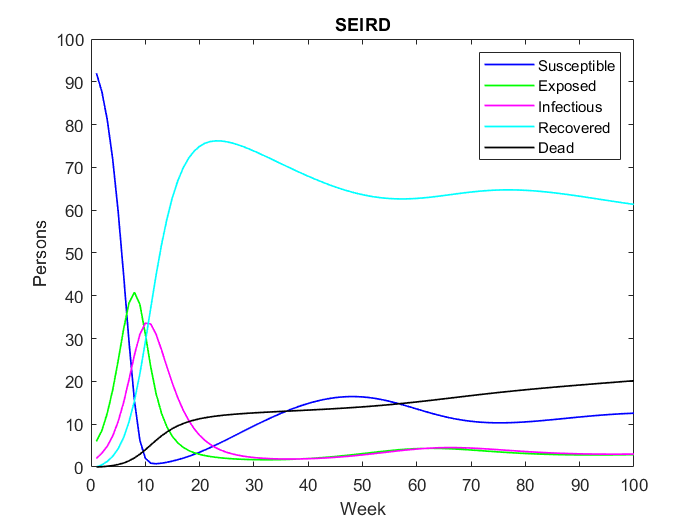

% Plot SEIRD
plot(W_seird, S_seird, 'b-', 'LineWidth', 1, 'DisplayName', 'Susceptible');
hold on;
plot(W_seird, E_seird, 'g-', 'LineWidth', 1, 'DisplayName', 'Exposed');
plot(W_seird, I_seird, 'm-', 'LineWidth', 1, 'DisplayName', 'Infectious');
plot(W_seird, R_seird, 'c-', 'LineWidth', 1, 'DisplayName', 'Recovered');
plot(W_seird, D_seird, 'k-', 'LineWidth', 1, 'DisplayName', 'Dead');
hold off;
xlabel("Week")
ylabel("Persons")
legend()
title("SEIRD")

## `Interpretation`

The results make it clear that both the models have entirely different use-cases and successes in predicting the behavior of a virus. Their divergence in both the intensity and time of the second wave may almost entirely be attributed to the inclusion of the Exposed stock. Scenarios without the Dead stock show little to no change in overall trends, while those with larger values of alpha - the parameter that affects flow from Exposed to Infectious - close the gap between the two models. Making alpha larger makes the inclusion of the Exposed stock increasingly negligible.

A few limitations of the SIR vs SEIRD model comparison include:

1) Inaccuracies in the starting value of Exposed individuals -

- The starting value of the Exposed individuals stock is currently set at 6. This has proven to be a good starting value because too low of a number causes the Infectious stock to lose drop before it begins to increase. This delays the start of the SEIRD model and causes additional "waves" to be detected. However, this is not a one-size-fits-all solution. The value of the Exposed stock should relate to the infectivity because it is meant to smoothen the curve whose slope is a function of infectivity. Otherwise, the graph will seem to "jump" in an unnatural way at the start.

2) The inability to line up the first waves perfectly horizontally -

- Due to the resolution of the model being in weeks, the peakShift vector can only hold integer values. This leads to a low-resolution horizontal matching of Wave 1. At some infectivities, the waves align perfectly, but at others, they seem shifted slightly one way or another.

The next steps to continue developing the SEIRD model would involve fixing the standardization of infectivity to include changing the number of exposed people in the model and also making the curve smoother, especially where there seem to be artifacts due to the constant number of exposed people. It would also be beneficial to run the model on a daily-basis rather than weekly.